% Load the pre-trained model
load Neural_Networks\5-signs\resnet_18\resnet.mat;

% Ask the user to select a folder containing the images
inputFolder = uigetdir(pwd, 'Select the folder containing images');

% Load the test dataset
signds = imageDatastore(inputFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split the dataset into training and testing sets
[signTrain, signTest] = splitEachLabel(signds, 0.8, "randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224], signTrain);
resizeTestImgs = augmentedImageDatastore([224 224], signTest);

% Set the number of classes
numClasses = numel(categories(signds.Labels));

% Set training options
opts = trainingOptions("sgdm", "InitialLearnRate", 0.001, "MaxEpochs", 5, "VerboseFrequency", 2);

% Train the network
[Network1, info] = trainNetwork(resizeTrainImgs, resnet, opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:35 |       17.19% |       2.9379 |          0.0010 |
|       1 |           2 |       00:01:09 |       19.53% |       3.0036 |          0.0010 |
|       1 |           4 |       00:02:15 |       21.09% |       2.5493 |          0.0010 |
|       2 |           6 |       00:03:28 |       38.28% |       2.1518 |          0.0010 |
|       2 |           8 |       00:04:46 |       51.56% |       1.6028 |          0.0010 |
|       3 |          10 |       00:06:07 |       69.53% |       1.2312 |          0.0010 |
|       3 |          12 |  

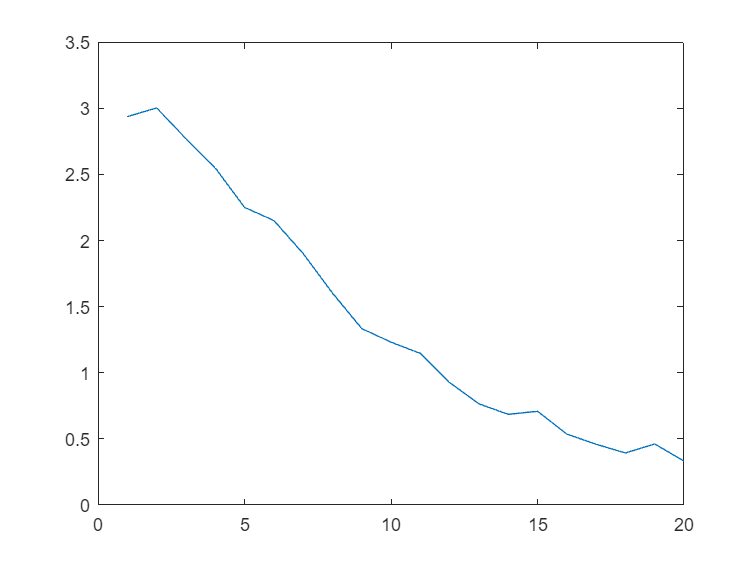


% Plot training loss
plot(info.TrainingLoss);


% Save the "signTest" dataset in respective folders
outputTestFolder = "D:\college\FYP\test_images\output"; % Change this path as per your requirement

for i = 1:numel(signTest.Files)
    imgPath = signTest.Files{i};
    [~, imgName, imgExt] = fileparts(imgPath);
    imgLabel = char(signTest.Labels(i));
    outputFolder = fullfile(outputTestFolder, imgLabel);
    
    % Create the class label folder if it doesn't exist
    if ~exist(outputFolder, 'dir')
        mkdir(outputFolder);
    end
    
    % Copy the image to the respective folder
    outputImgPath = fullfile(outputFolder, strcat(imgName, imgExt));
    copyfile(imgPath, outputImgPath);
end

% Evaluate Performance
signPrediction = classify(Network1, resizeTestImgs);
signActual = signTest.Labels;

% Calculate accuracy
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect / numel(signPrediction);

% Display accuracy
fprintf("Accuracy: %.2f%%\n", fracCorrect * 100);

Accuracy: 87.50%


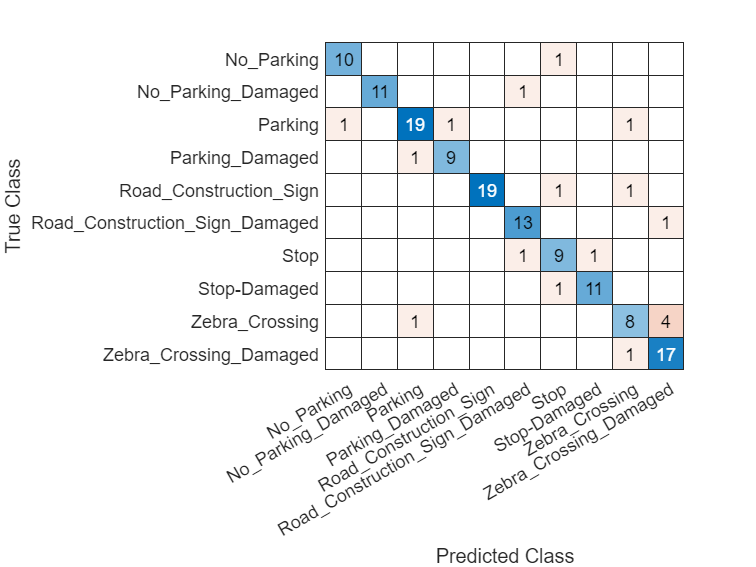


% Confusion Chart
confusionchart(signActual, signPrediction);